clear 
clc
fs = 41.667e3

fs = 41667

numSamples = 190;
numMics = 8;
micList = 0:6

micList =      0     1     2     3     4     5     6


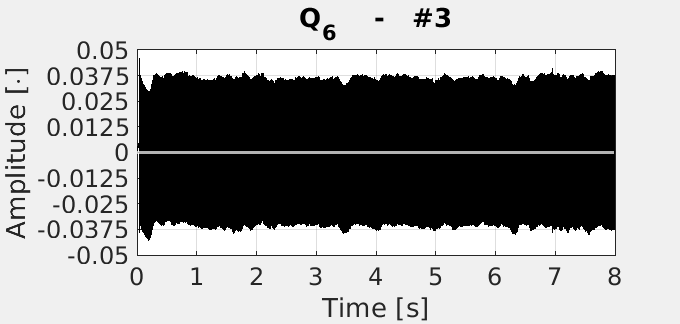

gains = zeros(7,3);
dcOffset = zeros(7,3);
for m = 1:7
    for r = 1:3
        %fileID = fopen('mic_0_num_0');
        fileID = fopen('mic_'+string(m-1)+'_num_'+string(r-1));
        data = fread(fileID,'single');
        data = data/(power(2,31)-1);
        
        onePacketLength = numSamples*numMics ;
        numPacketsInData = floor(length(data)/onePacketLength);
        micData = zeros(numSamples,1);
        for i = 0:numPacketsInData-1
            micData = [micData; data(1+(micList(m)*numSamples)+i*onePacketLength:(micList(m)*numSamples)+i*onePacketLength+numSamples)];
        end
        micData = micData((numSamples+1):8*fs);
        dcOffset(m,r) = mean(micData);
        gains(m,r) = mean((micData-dcOffset(m,r)).^2);


        colorList = ["r" "g" "b" "c" "m" "y" "k"];
        set(gcf,'Visible','on', 'Units', 'centimeters',...
          'OuterPosition', [0 0 18 11])
        plot(0:1/fs:(length(micData)-1)/fs,micData, "Color", colorList(m))
        hold on
        title('Q_' + string(m-1) + '    -   #' + string(r), 'FontSize', 22)
        xlabel('Time [s]', 'FontSize', 20)
        ylabel('Amplitude [\cdot]', 'FontSize', 20)
        
        if colorList(m) == "k"
            yline(dcOffset(m,r), 'LineWidth', 2, 'Color', 'w')
        else
            yline(dcOffset(m,r), 'LineWidth', 2)
        end
        grid
        ylim([-0.05 0.05])
        xlim([0 8])
        ytickList = linspace(-0.05,0.05,9);
        yticks(ytickList(1:1:end))
        yticklabels(string(ytickList(1:1:end)))
        xtickList = linspace(0,8,9);
        xticks(xtickList(1:1:end))
        xticklabels(string(xtickList(1:1:end)))
        ax = gca;
        ax.FontSize = 18;
        %legend('Output data', 'Mean')
        hold off
        exportgraphics(gcf,'post_mic_'+string(m-1)+'_num_'+string(r-1)+'.pdf')
    end
end


%hold off
gains

gains = 1.0e-03 *

    0.7347    0.7319    0.7206
    0.6380    0.6550    0.6681
    0.6013    0.5920    0.6129
    0.6912    0.6961    0.6803
    0.7439    0.7547    0.7842
    0.6900    0.6967    0.7063
    0.6754    0.6653    0.6487



mean(gains')

ans = 1.0e-03 *

    0.7291    0.6537    0.6020    0.6892    0.7609    0.6977    0.6631



max(mean(gains'))./mean(gains')

ans =     1.0437    1.1641    1.2639    1.1040    1.0000    1.0907    1.1475



normfactor = sqrt(max(mean(gains'))./mean(gains'))

normfactor =     1.0216    1.0789    1.1242    1.0507    1.0000    1.0444    1.0712


## Load everything

fileID = fopen('mic_0_num_0');
data = fread(fileID,'single');
data = data/(power(2,31)-1);
onePacketLength = numSamples*numMics 

onePacketLength = 1520

numPacketsInData = floor(length(data)/onePacketLength)

numPacketsInData = 1755

splitdata = zeros(numSamples,numMics);
for i = 0:numPacketsInData-1
    splitdata = [splitdata; reshape(data(i*onePacketLength+1:(i+1)*onePacketLength),[],numMics)];
end
splitdata = splitdata(numSamples+1:end,:)'

splitdata =     0.0000    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0002    0.0002    0.0001    0.0001    0.0001    0.0002    0.0002    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0001    0.0001    0.0001    0.0002    0.0001    0.0002    0.0002    0.0002
    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0048    0.0048    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0049    0.0049    0.0049    0.0049    0.0049    0.0050    0.0049    0.0048    0.0049    0.0049    0.0050    0.0048    0.0049    0.0049    0.0049    0.0050    0.0049    0.0049    0.0050    0.0049    0.0050    0.0050    0.0050    0.0051    0.0050    0.0050    0.0049    0.0049    0.0050    0.0